# Bill and Ari Solar House Model

## Question

According to [https://www.pnas.org/content/117/32/19122](https://www.pnas.org/content/117/32/19122), 20% of America’s greenhouse house gas emissions comes from household energy use, such as for climate control and appliance use. An efficient and comfortable solar house design would help greatly reduce household energy greenhouse gas emissions by reducing climate control energy needed. However, to have widespread adoption of solar houses, they need to be comfortable. This raises the question: how can we build the most comfortable passive solar house? 

However, to answer this question, one must first answer the question of what is a comfortable house? While having a certain average temperature is nice, ultimately it doesn’t matter if your house averages at a comfortable 23deg C when it fluctuates between 0 deg C at night and 35 deg C during noon. Thus, here we define comfort as having the smallest temperature variations over time while remaining within a livable temperature rang, which we deifne here as between 15deg C and 25 deg C. 

Thus, in this project we hope to find the optimal design for the passive solar house that maximizes comfort.

## Model

### Model Derviation:

To answer our question, we will build a numerical model of a house that will allow us to simulate the house’s temperature over the span of a year given a set of parameters describing the house. Once we have this model, we can then parameter sweep to examine how different parameters affect the mean and range of the temperature within the house.

The Department of Energy passive solar home design packet contains the following diagram illustrating the mechanisms for energy transport within a passive solar house:

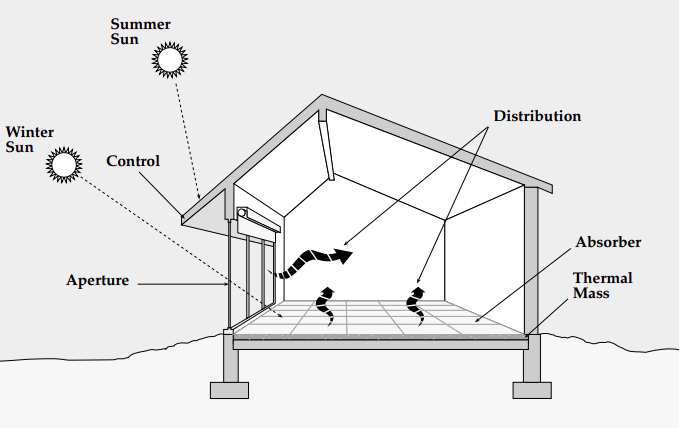

For us to model this house while keeping the project within a reasonable scope, we have made a couple assumptions:

- For the structure of the house, we are assuming the only three materials used in the construction are concrete, polyurethane foam, and glass. In our model house, the walls are entirely made of foam, the floor is made entirely of concrete, with a layer of insulation underneath, and the aperture is entirely made of insulating glass.

- For the environment of the house, we are using an incredibly simple model for the temperature of the environment. The temperature of the ground is a single sinusoidal wave with a period of 1 year, and the temperature of the air outside is the temperature of the ground, with another 24 hour period sinusoid layered on top. This obviously drastically simplifies actual air and ground temperature changes.

- For our insolation model, we are making yet another major assumption: we are assuming that throughout the whole year the house is always pointed directly towards the sunrise, with the aperture being perpendicular to the path traveled by the sun. In the real world, the azimuth of the sun actually changes throughout the year, and so to build a house that constantly faces the sunrise one would have to mount the house on a giant turntable and rotate the house throughout the year.

While these assumptions are all simplifications and abstractions, they do not fundamentally change the mathematical model of the house - it is only a matter of tweaking parameters, of numerical inaccuracy, Thus, while we will not be able to directly use the building design parameters generated by the model and the parameter sweeper, the conclusions we can draw from this project will still be valuable when considering how a passive solar house should be designed.

 From this set of abstractions, we can then build the model of the house represented here with our schematic drawing.

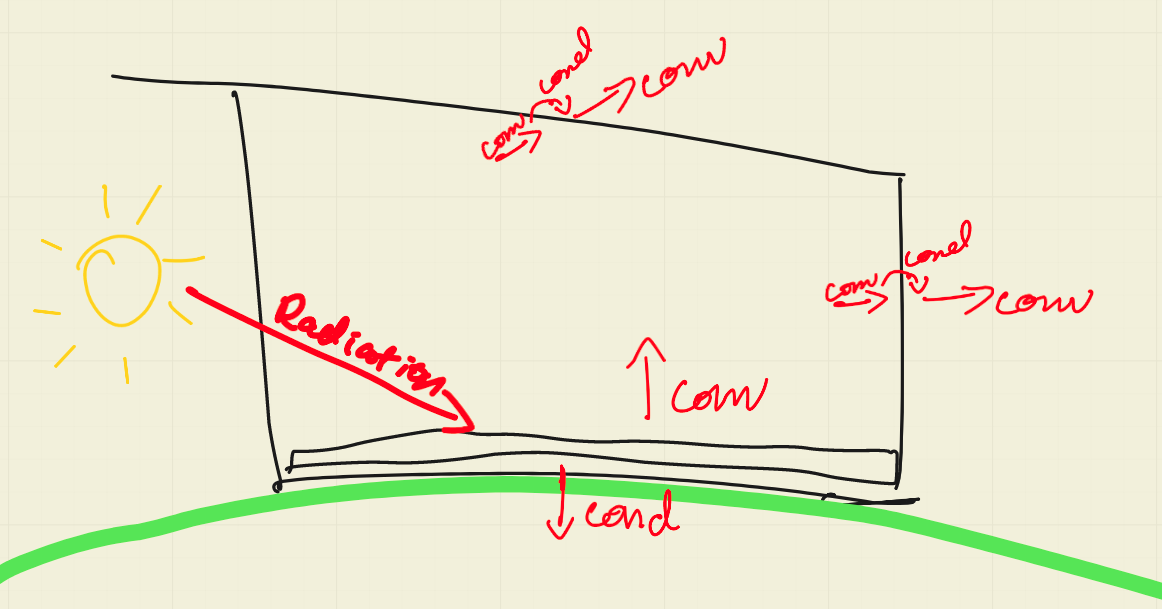

From this schematic, we can then generate a stock and flow diagram:

#### 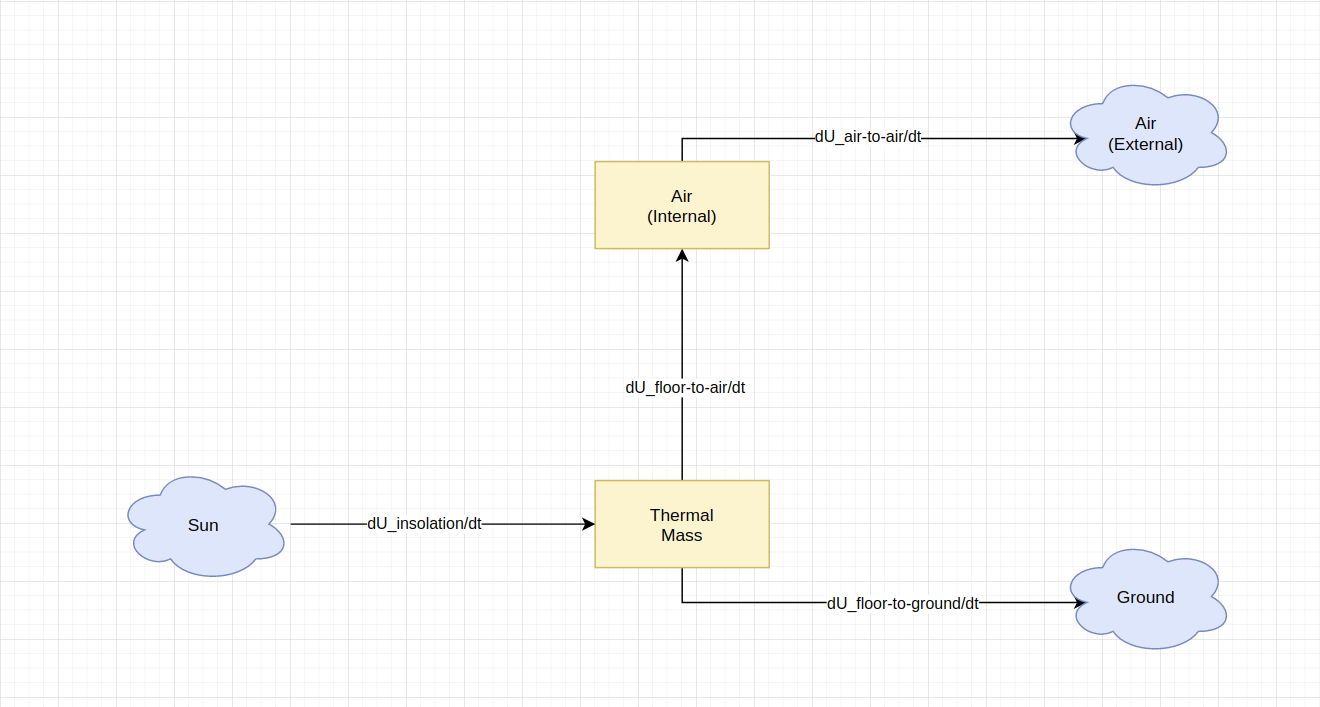

### Consolidated stock and flows:

From the stock and flow diagram we can then generate these equations for the total flows in and out of each stock:


$$\frac{dU_{air}}{dt} = \frac{dU_{floor-to-air}}{dt} - \frac{dU_{air-to-air}}{dt} \\

\frac{dU_{floor}}{dt} = \frac{dU_{insolation}}{dt} - \frac{dU_{floor-to-ground}}{dt} -  \frac{dU_{floor-to-air}}{dt} \\$$


### Equations for individual flows:

#### Energy flow from conduction/convection

General equation for heat flow when given resistances:


$$\frac{dU_{flow}}{dt} = \frac{-1}{R_{total}}\Delta T$$


For the individual heat flows, we then have:


$$\frac{dU_{floor-to-ground}}{dt} = \frac{-1}{R_{floor-to-ground}}(T_{ground} - T_{floor}) \\

\frac{dU_{floor-to-air}}{dt} = \frac{-1}{R_{floor-to-air}}(T_{air-inside} - T_{floor})\\

\frac{dU_{air-to-air}}{dt} = \frac{-1}{R_{air-to-air}}(T_{air-outside} - T_{air-inside})$$


#### Energy from radiation (insolation)

Equation for energy from insolation:


$$\frac{dU_{insolation}}{dt} = eIA_{insolation}$$


Now to implement these equations, we just need to derive the resistances, and find the temperatures in relation to energy

### Resistances:

$R_{air-air} = \frac{1}{2 \frac{1}{h_{air}(A_{w} + A_{ceil})} + \frac{d_{w}}{(A_{w} + A_{ceil})k_{w}} } + \frac{1}{2 \frac{1}{h_{air}A_{a}} + \frac{d_{a}}{A_{a}k_{a}} } \\
 = \frac{1}{2 \frac{1}{h_{air}(A_{w} + A_{f})} + \frac{d_{w}}{(A_{w} + A_{f})k_{w}} } + \frac{1}{2 \frac{1}{h_{air}A_{a}} + \frac{d_{a}}{A_{a}k_{a}} }$    and since the house is a box, $A_{ceil} = A_f $


$$R_{floor-air} = \frac{1}{h_{air} A_{f}}$$



$$R_{floor-ground} = \frac{d}{A_fk_f$$


### Temperatures:

Formula for converting energy into temperature: $U = mcT$. Thus,

$T_{ground}$ = Given

$T_{air-outside}$= Given


$$T_{floor} = \frac{U_{floor}}{m_{floor}\ c_{floor}}$$



$$T_{air-inside} = \frac{U_{air-inside}}{m_{air-inside}\ c_{air}}$$


### Putting it all together


$$\frac{dU_{air}}{dt} = \frac{-1}{R_{floor-to-air}}(T_{air-inside} - T_{floor}) - \frac{-1}{R_{air-to-air}}(T_{air-outside} - T_{air-inside}) \\

\frac{dU_{floor}}{dt} = eIA_{insolation} - \frac{-1}{R_{floor-to-ground}}(T_{ground} - T_{floor}) - \frac{-1}{R_{floor-to-air}}(T_{air-inside} - T_{floor}) \\$$



$$T_{floor} = \frac{U_{floor}}{m_{floor}\ c_{floor}}$$



$$T_{air-inside} = \frac{U_{air-inside}}{m_{air-inside}\ c_{air}}$$



$$R_{air-air} = \frac{1}{2 \frac{1}{h_{air}(A_{w} + A_{f})} + \frac{d_{w}}{(A_{w} + A_{f}) k_{w}} } + \frac{1}{2 \frac{1}{h_{air}A_{a}} + \frac{d_{a}}{A_{a}k_{a}} }$$



$$R_{floor-air} = \frac{1}{h_{air} A_{f}}$$



$$R_{floor-ground} = \frac{d}{A_fk_f$$


### Model Verification

% Constant area
area_floor = 350;
height_aperture = 5;
width_aperture = 10;

% Parameters to sweep
thickness_floor = 0.2;
thickness_insulation = 0.2;

end_day = 2;
timespan = [1, end_day * (24 * 60 * 60)]; % Convert date time ranges to seconds
max_timestep = 1000;

[T_base, Y_base, debug] = house_simulate(timespan, max_timestep, height_aperture, width_aperture, area_floor, thickness_floor, thickness_insulation);

% Seconds to days
T_base = T_base / (24 * 60 * 60);
debug(:, 1) = debug(:, 1) / (24 * 60 * 60);

% K to C
Y_base(:, 1:2) = Y_base(:, 1:2) - 273.15;
debug(:, 6:7) = debug(:, 6:7) - 273.15;

% J to kJ
debug(:, 2:5) = debug(:, 2:5) / 1000;

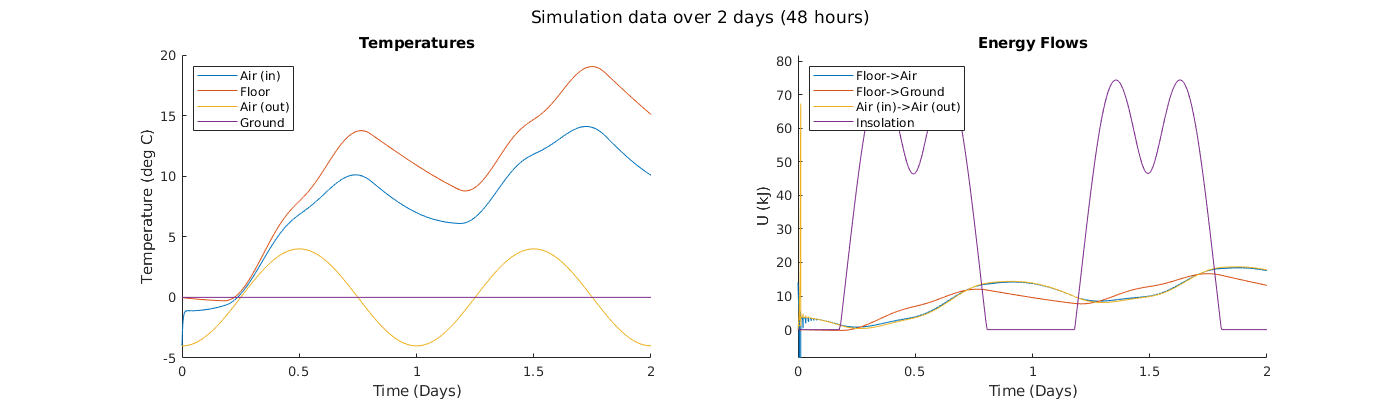

figure(1); clf;
set(gcf, 'position', [0 0 1400 400])
sgtitle('Simulation data over 2 days (48 hours)')

subplot(1, 2, 1);
hold on;
plot(T_base, Y_base(:, 1));
plot(T_base, Y_base(:, 2));
plot(debug(:, 1), debug(:,6))
plot(debug(:, 1), debug(:,7))
hold off;
legend("Air (in)", "Floor", "Air (out)", "Ground", 'location', 'nw');
xlabel("Time (Days)");
ylabel("Temperature (deg C)");
title("Temperatures");

subplot(1, 2, 2)
hold on;
plot(debug(:, 1), debug(:, 2))
plot(debug(:, 1), debug(:, 3))
plot(debug(:, 1), debug(:, 4))
plot(debug(:, 1), debug(:, 5))
hold off;
legend("Floor->Air", "Floor->Ground", "Air (in)->Air (out)", "Insolation", 'location', 'nw');
xlabel("Time (Days)");
ylabel("U (kJ)");
title("Energy Flows");

ylim([-0.25 max(max(debug))*1.1])

<Figure explanation needed>

timespan_1month = [1, 30 * (24 * 60 * 60)];
timespan_1year = [1, 365 * (24 * 60 * 60)];
max_timestep = 1000;

% Simulate for three different timespans
[T_1month, Y_1month, ~] = house_simulate(timespan_1month, max_timestep, height_aperture, width_aperture, area_floor, thickness_floor, thickness_insulation);
[T_1year, Y_1year, ~] = house_simulate(timespan_1year, max_timestep * 10, height_aperture, width_aperture, area_floor, thickness_floor, thickness_insulation);

% Seconds to days
T_1month = T_1month / (24 * 60 * 60);
T_1year = T_1year / (24 * 60 * 60);

% K to C
Y_1month(:, 1:2) = Y_1month(:, 1:2) - 273.15;
Y_1year(:, 1:2) = Y_1year(:, 1:2) - 273.15;

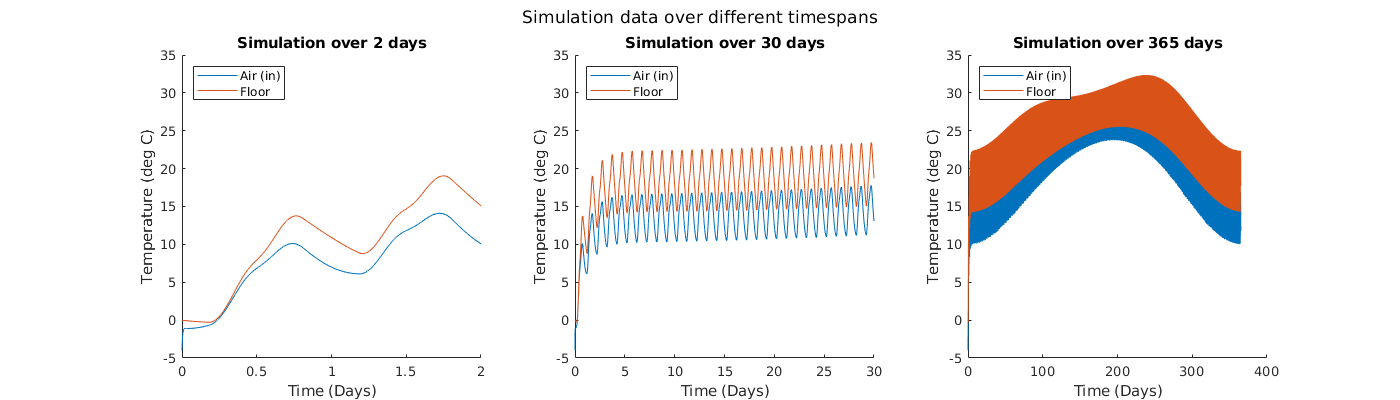

clf; figure(2);
set(gcf, 'position', [0 0 1400 400])
sgtitle('Simulation data over different timespans')

subplot(1, 3, 1);
hold on;
plot(T_base, Y_base(:, 1));
plot(T_base, Y_base(:, 2));
hold off;
legend("Air (in)", "Floor", 'location', 'nw');
xlabel("Time (Days)");
ylabel("Temperature (deg C)");
title("Simulation over 2 days");

subplot(1, 3, 2);
hold on;
plot(T_1month, Y_1month(:, 1));
plot(T_1month, Y_1month(:, 2));
hold off;
legend("Air (in)", "Floor", 'location', 'nw');
xlabel("Time (Days)");
ylabel("Temperature (deg C)");
title("Simulation over 30 days");

subplot(1, 3, 3);
hold on;
plot(T_1year, Y_1year(:, 1));
plot(T_1year, Y_1year(:, 2));
hold off;
legend("Air (in)", "Floor", 'location', 'nw');
xlabel("Time (Days)");
ylabel("Temperature (deg C)");
title("Simulation over 365 days");

fig2_axes = findall(gcf, 'type', 'axes');
linkaxes(fig2_axes, 'y');

<Figure explanation needed>

timespan_10days = [1, 10 * (24 * 60 * 60)];
[T_thin, Y_thin, ~] = house_simulate(timespan_10days, max_timestep, height_aperture, width_aperture, area_floor, thickness_floor, thickness_insulation);

Ok now we change parameters

Insulation thickness - should only increase temperature, shouldn't affect oscillations much

% Compare base case to thicker walls
[T_thickwalls, Y_thickwalls, ~] = house_simulate(timespan_10days, max_timestep, height_aperture, width_aperture, area_floor, thickness_floor, thickness_insulation * 2);

T_thin = T_thin / (24 * 60 * 60);
T_thickwalls = T_thickwalls / (24 * 60 * 60);

Y_thin = Y_thin - 273.15;
Y_thickwalls = Y_thickwalls - 273.15;

mean_thin = movmean(Y_thin(:, 1), length(Y_thin(:, 1)) / 10);
mean_thick = movmean(Y_thickwalls(:, 1), length(Y_thickwalls(:, 1)) / 10);

min_thin = movmin(Y_thin(:, 1), length(Y_thin(:, 1)) / 10);
min_thick = movmin(Y_thickwalls(:, 1), length(Y_thickwalls(:, 1)) / 10);

max_thin = movmax(Y_thin(:, 1), length(Y_thin(:, 1)) / 10);
max_thick = movmax(Y_thickwalls(:, 1), length(Y_thickwalls(:, 1)) / 10);

range_thin = max_thin - min_thin;
range_thick = max_thick - min_thick;

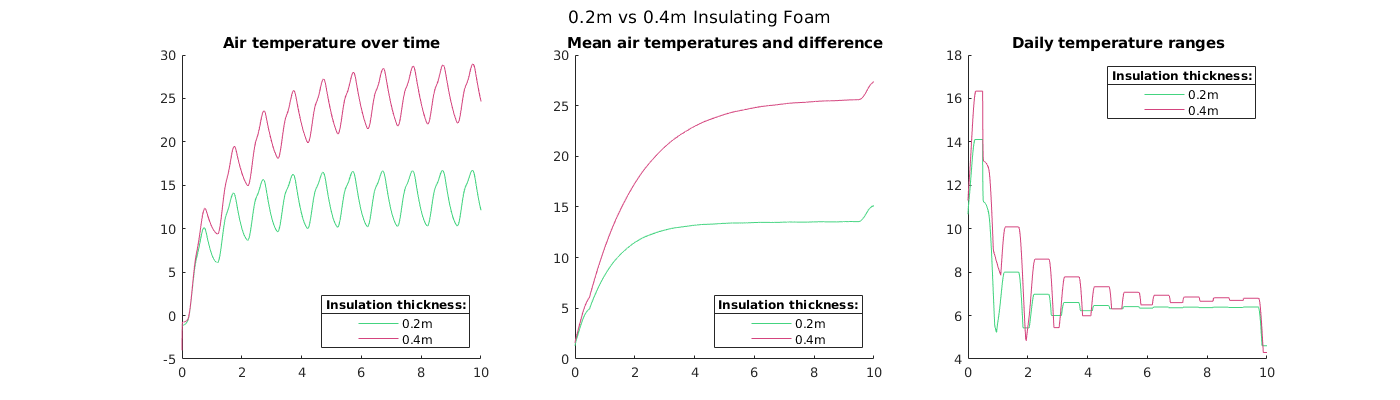

% Only plotting air
clf; figure(3);
set(gcf, 'position', [0 0 1400 400])
sgtitle('0.2m vs 0.4m Insulating Foam')

subplot(1, 3, 1);
hold on;
plot(T_thin, Y_thin(:, 1), 'Color', '#44d480');
plot(T_thickwalls, Y_thickwalls(:, 1), 'Color', '#d4447e');
lgd = legend('0.2m', '0.4m', 'Location', 'se');
title(lgd, 'Insulation thickness:')
title("Air temperature over time")
hold off;

subplot(1, 3, 2);
hold on;
plot(T_thin, mean_thin, 'Color', '#44d480');
plot(T_thickwalls, mean_thick, 'Color', '#d4447e');
lgd = legend('0.2m', '0.4m', 'Location', 'se');
title(lgd, 'Insulation thickness:');
title("Mean air temperatures and difference");

subplot(1, 3, 3)
hold on;
plot(T_thin, range_thin, 'Color', '#44d480');
plot(T_thickwalls, range_thick, 'Color', '#d4447e');
lgd = legend('0.2m', '0.4m', 'Location', 'ne');
title(lgd, 'Insulation thickness:')
title("Daily temperature ranges")

<Figure explanation needed>

Ok now we try changing the floor thickness

% Compare base case to thicker floor
[T_thickfloor, Y_thickfloor, ~] = house_simulate(timespan_10days, max_timestep, height_aperture, width_aperture, area_floor, thickness_floor * 2, thickness_insulation);

T_thickfloor = T_thickfloor / (24 * 60 * 60);

Y_thickfloor = Y_thickfloor - 273.15;

mean_thin = movmean(Y_thin(:, 1), length(Y_thin(:, 1)) / 10);
mean_thick = movmean(Y_thickfloor(:, 1), length(Y_thickfloor(:, 1)) / 10);

min_thin = movmin(Y_thin(:, 1), length(Y_thin(:, 1)) / 10);
min_thick = movmin(Y_thickfloor(:, 1), length(Y_thickfloor(:, 1)) / 10);

max_thin = movmax(Y_thin(:, 1), length(Y_thin(:, 1)) / 10);
max_thick = movmax(Y_thickfloor(:, 1), length(Y_thickfloor(:, 1)) / 10);

range_thin = max_thin - min_thin;
range_thick = max_thick - min_thick;

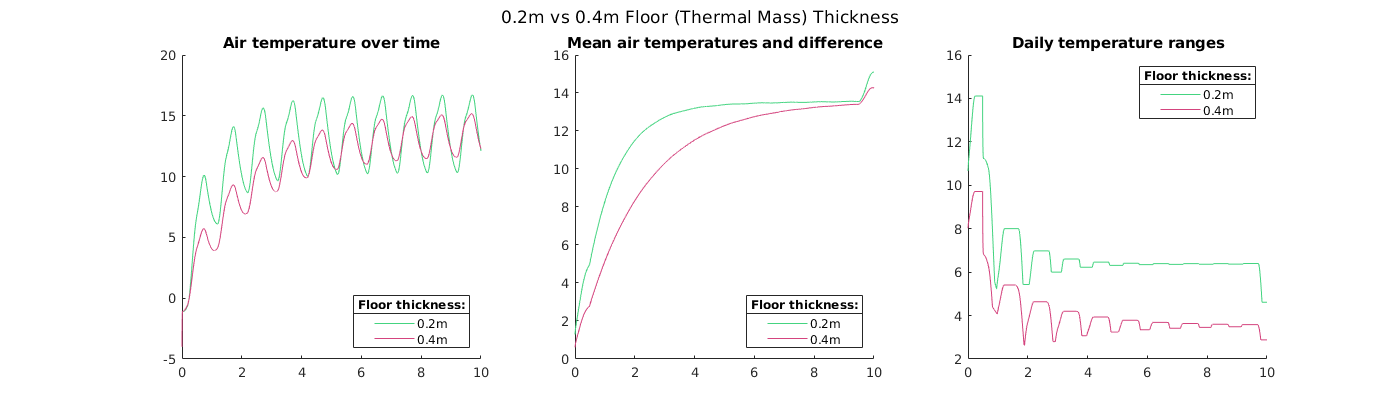

% Only plotting air
clf; figure(4);
set(gcf, 'position', [0 0 1400 400])
sgtitle('0.2m vs 0.4m Floor (Thermal Mass) Thickness')

subplot(1, 3, 1);
hold on;
plot(T_thin, Y_thin(:, 1), 'Color', '#44d480');
plot(T_thickfloor, Y_thickfloor(:, 1), 'Color', '#d4447e');
lgd = legend('0.2m', '0.4m', 'Location', 'se');
title(lgd, 'Floor thickness:')
title("Air temperature over time")
hold off;

subplot(1, 3, 2);
hold on;
plot(T_thin, mean_thin, 'Color', '#44d480');
plot(T_thickfloor, mean_thick, 'Color', '#d4447e');
lgd = legend('0.2m', '0.4m', 'Location', 'se');
title(lgd, 'Floor thickness:');
title("Mean air temperatures and difference");

subplot(1, 3, 3)
hold on;
plot(T_thin, range_thin, 'Color', '#44d480');
plot(T_thickfloor, range_thick, 'Color', '#d4447e');
lgd = legend('0.2m', '0.4m', 'Location', 'ne');
title(lgd, 'Floor thickness:')
title("Daily temperature ranges")

<Figure explanation needed>

### Validation

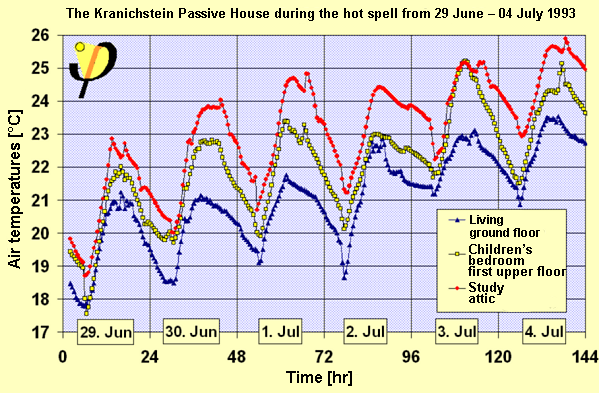

<Run simulation over 144 hours in the summer>

## Results

## Interpretation